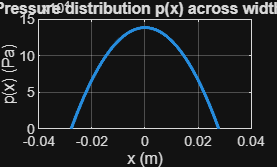

% https://mydailyengineering.wordpress.com/dry-steering/
% bilder av cad ligger i https://drive.google.com/drive/u/1/folders/1R42UJ85xGUDm-tD5RUjfcWQPFO0rt5rP
clc; clear; close all;

a_mm = 55.67; % mm kort side kontaktflate
b_mm = 154; % mm Langside kontaktflate
Fz_kg = 80.575; % kg vekt på hjulet
sigma_deg = 7.98; % deg KPI
tau_deg = 6.18; % deg caster
r_dyn_mm = 203.2; % mm radius hjul hjul
CD_mm = 28.48; % mm   r_dyn * tan sigma
rs_mm = 10.05; % mm  skrubb radie, DO linja
delta_deg = linspace(-31, 31, 1000);   % deg styrevinkel

g = 9.81;         % m/s^2
a = a_mm*1e-3;    % m  
b = b_mm*1e-3;    % m
Fz = Fz_kg*g;      % N
x = linspace(-a/2, a/2, 1000);   % m
sigma = deg2rad(sigma_deg); % rad
tau = deg2rad(tau_deg); % rad
r_dyn = r_dyn_mm*1e-3; % m
CD = CD_mm*1e-3; % m
rs = rs_mm*1e-3; % m
delta = deg2rad(delta_deg); % rad

% Pressure Distribution
p = (6*Fz/(a^3*b)) .* (a/2 - x) .* (a/2 + x);  % Pa (N/m^2)

plot(x, p, 'LineWidth', 2)
grid on
xlabel('x (m)')
ylabel('p(x) (Pa)')
title('Pressure distribution p(x) across width a')

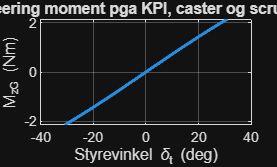


% Gravity based aligning moment
MzG = Fz * (rs + r_dyn*tan(sigma)) .* cos(sigma) .* sin(sigma) .* cos(tau) .* sin(delta); % Nm

figure
plot(delta_deg, MzG, 'LineWidth', 2)
grid on
xlabel('Styrevinkel \delta_t (deg)')
ylabel('M_{zG} (Nm)')
title('Dry steering moment pga KPI, caster og scrub radius')


% Friction based moment
x0 = -a/2;
x1 = a/2;
y0 = -b/2; 
y1 = b/2; 

e0 = 22.36; %mm
beta = 10; %degrees

ex = e0*cosd(beta);
ey = e0*sind(beta);
mu = 1.75; %friction coeff

fun = @(x,y) ((6*Fz)/(a^3*b) .* (a/2 - x) .* (a/2 + x)).*(sqrt((ex - x).^2 + (ey - y).^2));

Mzft = mu * integral2(fun, x0, x1, y0, y1);

Mzf = Mzft*cosd(sigma_deg)*cosd(tau_deg); %Nmm
Mzf = Mzf/1000; %Nm
Mfo = 0.4; %Nm

Lk = 84.55; %mm
theta_tk = linspace(84.17, 132.55,1000); %degrees
theta_rt = linspace(177.21,179.95,1000); %degrees
theta_kk = 68.54; %degrees
Frt = 10; %N ÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆÆæ
R = 47.5/2; %mm
L = Lk .* sind(theta_tk);
Ftt = Frt .* cosd(pi-theta_rt);
i = (Ftt .* L .* cosd(theta_kk-(pi/2)))/(Frt .* R);

Mz = ((Mzf+MzG)./i) + Mfo

Mz =   -20.0321  -20.0330  -20.0340  -20.0349  -20.0359  -20.0369  -20.0379  -20.0390  -20.0400  -20.0411  -20.0421  -20.0432  -20.0444  -20.0455  -20.0466  -20.0478  -20.0490  -20.0502  -20.0514  -20.0526  -20.0538  -20.0551  -20.0564  -20.0577  -20.0590  -20.0603  -20.0616  -20.0630  -20.0644  -20.0657  -20.0671  -20.0686  -20.0700  -20.0715  -20.0729  -20.0744  -20.0759  -20.0774  -20.0790  -20.0805  -20.0821  -20.0837  -20.0852  -20.0869  -20.0885  -20.0901  -20.0918  -20.0935  -20.0952  -20.0969


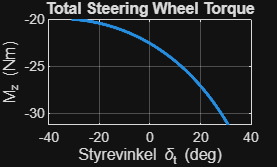


figure
plot(delta_deg, Mz, 'LineWidth', 2)
grid on
xlabel('Styrevinkel \delta_t (deg)')
ylabel('M_{z} (Nm)')
title('Total Steering Wheel Torque')